SAMPLES_SECOND = 8000;

Generar RUIDO GAUSIANO

8000 por muestras

 por segundos

0 por 0dbW

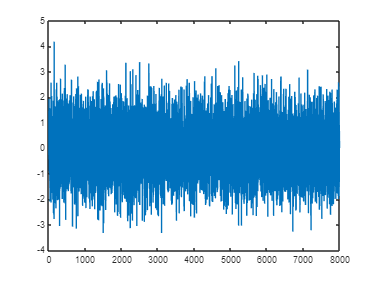

gausian_noise = wgn(SAMPLES_SECOND,1,-.0001,1);
figure(1);
plot(gausian_noise)

LECTURA DE AUDIO DE VOZ

8,000 Muestras por segundo

monoaural

PCM 8 Bits por muestras

[y, Fs] = audioread("Audios\grape-juice.wav");
%{
sound(y,Fs);
y;
plot(y);
%}

realizar down sampling

    -resamplee Fs -> 8k

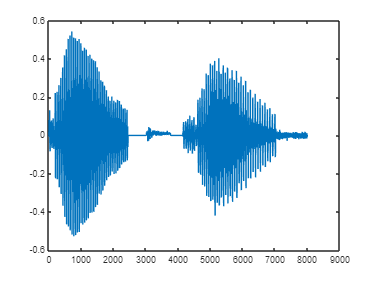

s_down_resample = resample(y, SAMPLES_SECOND, Fs);

m_t = s_down_resample(1:(SAMPLES_SECOND+1)); %cut one second final message signal
plot(m_t);

%sound(m_t,SAMPLES_SECOND);

NORMALIZAR 

    0 - 255

    0 - 1

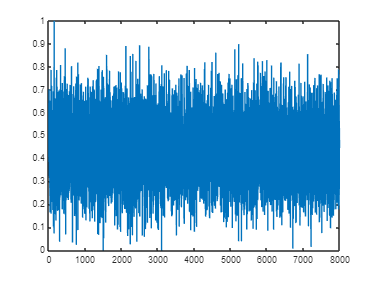

%norm_value = normalize(m_t,'range');
norm_value = rescale(norm_value, 0, 255);
%plot(norm_value);
gausian_noise = normalize(gausian_noise,'range');
plot(gausian_noise);

potencia promedio de la señal

Relaciones SNR

potSEÑAL/pot ruido

cual es la relacion señal a ruido en que la voz es inteligible?

Cual es la RSR en que la voz tiene calidad buena?

FORMULAS